# Seminar 1

## PROBLEM 13

File SM22_Seminar_1_13.xlsx contains data from the marks obtained by students in 2 out of the 5 labs of Statistical Models in the course 2019-2020 (first 2 columns in each row). The last column contains a binary indicator of whether the corresponding student passed the course (1) or not (0). Therefore, we can consider that we have 2 random samples of 2 dimensions  each (students who passed the course and those who did not pass). For each of these two random samples, and assuming that they follow a multivariate normal distribution:

% Importing table

filename = 'semi1/SM22_Seminar_1_13.xlsx';
% check that working directory is ME-2024
raw = readtable(filename);

### a) Calculate and draw 95% confidence regions for the population means. Recall to consider separately the two populations of students (who passed and who did not pass) and therefore you will construct two separate confidence regions.

% passPopulationIdx = raw(:,3) == 1
% raw(:,3) == 1 equivalent to logical(raw(:,3))
% () return tables, {} return arrays
alpha = 0.05

alpha = 0.0500


passPopulation = raw{raw{:,3} == 1,[1, 2]};
noPassPopulation = raw{raw{:,3} == 0,[1, 2]};

smeanPass = smean(passPopulation);
disp('Pass Population Sample Mean:')

Pass Population Sample Mean:


disp(smeanPass);

    7.6250    8.4911




smeanNoPass = smean(noPassPopulation);
disp('No-Pass Population Sample Mean:')

No-Pass Population Sample Mean:


disp(smeanNoPass);

    6.1429    6.7679




sstdPass = sstd(passPopulation);
disp('Pass Population Standard Error:')

Pass Population Standard Error:


disp(sstdPass);

    2.2153    1.4549
    1.4549    1.5532




sstdNoPass = sstd(noPassPopulation);
disp('No-Pass Population Standard Error:')

No-Pass Population Standard Error:


disp(sstdNoPass);

    4.7184    1.5598
    1.5598    2.8506




% of the form px2
ciPass = confInterval(passPopulation, alpha);
disp('Pass Population CI:')

Pass Population CI:


disp(ciPass);

    6.8810    8.3690
    7.8681    9.1141




ciNoPass = confInterval(noPassPopulation, alpha);
disp('No-Pass Population CI:')

No-Pass Population CI:


disp(ciNoPass);

    4.4585    7.8272
    5.4586    8.0771



center =     7.6250    8.4911


axis =     0.1953   -0.7180
   -0.2447   -0.5729


xd =    -0.3131   -0.0000
   -0.3130   -0.0092
   -0.3130   -0.0184
   -0.3129   -0.0276
   -0.3128   -0.0367
   -0.3127   -0.0459
   -0.3125   -0.0551
   -0.3123   -0.0642
   -0.3121   -0.0734
   -0.3118   -0.0826


points =     7.5639    8.7158
    7.5661    8.7211
    7.5684    8.7263
    7.5706    8.7315
    7.5729    8.7367
    7.5752    8.7419
    7.5775    8.7470
    7.5797    8.7521
    7.5820    8.7572
    7.5843    8.7622


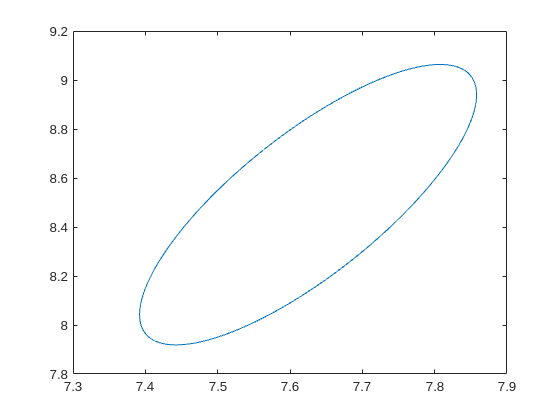

Error using annotation (line 109)
X and Y values must be between 0 and 1.

Error in code>drawCI (line 80)
    annotation('arrow', axis(1,:), axis(2,:), 'Units', 'norm')


drawCI(passPopulation, alpha)


function m = smean(pop)
    m = sum(pop, 1) / length(pop);
end

function s = sstd(pop)
    s = (pop-smean(pop))'*(pop-smean(pop)) / (length(pop)-1);
end

function ci = confInterval(pop, alpha)
    n = size(pop, 1);
    p = size(pop, 2);
    c = sqrt((n-1)*p / (n-p) * finv(1-alpha, p, n-p));
    s_diag = diag(sstd(pop)); % vector containing the diagonal only
    x_bar = smean(pop);
    ci = [x_bar' - c*sqrt(s_diag/n), x_bar' + c*sqrt(s_diag/n)];
end

function axis = getAxis(pop, alpha)
    n = size(pop, 1);
    p = size(pop, 2);
    c = sqrt((n-1)*p / (n-p) * finv(1-alpha, p, n-p));

    [eVec, eVal] = eig(sstd(pop));
    eVal = diag(eVal);

    axis = c * sqrt(eVal/n)' .* eVec;
end

function drawCI(pop, alpha)
    ci = confInterval(pop, alpha);
    center = smean(pop);
    axis = getAxis(pop, alpha);
    minor = norm(axis(:, 1));
    major = norm(axis(:, 2));

    t = -pi:0.01:pi;
    xd = [minor * cos(t)', major * sin(t)'];
    points = center + xd * axis;

    plot(points(:,1),points(:,2))
    % annotation('arrow', axis(1,:), axis(2,:))
    yline()
end

### b) Calculate 95% confidence intervals for the marks of the two groups of students for each lab.

### c) Based on your results in (a) and (b), is it possible to extract any conclusion regarding the average marks of these two labs between students who passed or failed the subject?